clear variables
close all
addpath('ngpca', 'data_sets_combined');
% Reproducability
rng(0)

## Create the NGPCA object

Parameters  

Name - Range - Default - Description 

"potentialFunction" - "AR", "N", "H", "VRV", "AV", "VRR" - "AR" - Defines the potential function used during the ranking process "temperature" - [0,1] - 0 - 0 = Softclustering more accurate but slower, 1 = Hardclustering "learningrate" - [0,0.99] - 0.99 - Defines the initial learning rate for all units "activity" - [0,1] - 1 - Defines the initial activity for all units "rho_init" - [0,1] - 0.99 - Defines the initial neighborhood range "rho_final" - [0,1] - 0.02 - Defines the final neighborhood range. Has to be smaller than rho_init "mu" - [0,1] - 0.005 - Low pass filter "rmax" - [0,inf] - 200 - Defines the strength of the adaptive term in the potential function. No effect in "N" and "H"

ngpca = NGPCA("temperature", 1);
disp(ngpca)

  NGPCA with properties:

     potentialFunction: "AR"
           temperature: 1
          learningRate: 0.9900
              activity: 1
              rho_init: 0.9900
             rho_final: 0.0200
                    mu: 0.0050
                  rmax: 200
           numberUnits: []
     PCADimensionality: []
    dataDimensionality: []
                   rho: 0
                 units: []
                lambda: 1
                     r: []
                    CI: []
                    DU: []
                   NMI: []
              filename: []
            iterations: []
                  data: []
           initialized: []



## Load data - The provided .mat files contain:

Name - Description Data - Training data gt - Ground truth cluster centers used for CI Eigenvectors and Eigenvalues used for CI label - Data point labels used for NMI and DU

ngpca.filename = 's1.mat';
load(ngpca.filename,'data','gt','label','eigenvalues','eigenvectors');
disp(head(data))

      664159      550946
      665845      557965
      597173      575538
      618600      551446
      635690      608046
      588100      557588
      582015      546191
      604678      574577



## Train on single data point

Parameters Name - Description "numberUnits" - Defines the number of units to be initialized "PCADimensionality" - Sets the dimensionality for all units

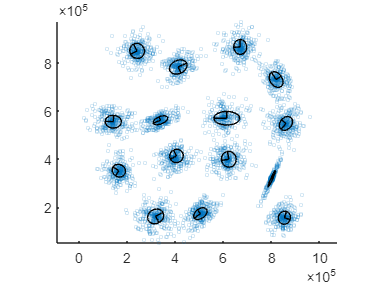

figure;
scatter(data(:,1), data(:,2),5,'o','MarkerFaceAlpha',.2,'MarkerEdgeAlpha',.2);
hold on;
axis equal;
axis manual;
for i = 1:20000
    % Sample a random data point in each iteration
    ngpca = fit_single(ngpca, data(ceil(size(data,1) .* rand), :), 15, "iterations", 20000, "PCADimensionality", 2);
    % Needed to overwrite the ngpca object if plotted in a loop to delete
    % units from previous plot
    if mod(i,2000) == 0
        ngpca = ngpca.draw();
    end
end

## Train on full data set

Mandatory parameters data - matrix where each row contains a n-dimensional data point numberUnits - Defines the number of units Minimal example: ngpca = fit_multiple(ngpca, [1,1;2,3;4,5], 2); The data vector is usually replaced by the data variale obtained from loading one of the data sets --- Optional parameters "iterations" - Defines the number of iterations "PCADimensionality" - Sets the dimensionality for all unitstic; Full example: ngpca = fit_multiple(ngpca, [1,1;2,3;4,5], 15, "iterations", 20000, "PCADimensionality", 2);

ngpca = fit_multiple(ngpca, data, 15, "iterations", 20000, "PCADimensionality", 2);

## Visualization

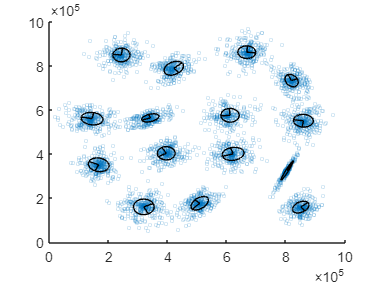

figure;
scatter(data(:,1), data(:,2),5,'o','MarkerFaceAlpha',.2,'MarkerEdgeAlpha',.2);
hold on;
ngpca.draw();

## Validation

ngpca = validation(ngpca, gt, eigenvalues, eigenvectors);
disp("CI:" + ngpca.CI)

CI:0
